clear all;
close all;

% 1. Definicja zmiennej s jako obiektu Transfer Function
s = tf('s'); 

% Przykład bardziej złożony (dwa szeregowo połączone człony)
Td = 2 * pi;
% G2 = (10 / (s + 1)) * (3 / (s + 5)) * exp(-s * Td);
G2 = (1 - exp(-s * Td)/(2 * pi * s));


% 3. Sprawdzenie wyniku i wykres Bode
disp('Transmitancja G2:');

Transmitancja G2:


disp(G2);

  ss with properties:

                A: 0
                B: 0.5000
                C: -0.3183
                D: 1
                E: []
          Offsets: []
           Scaled: 0
        StateName: {''}
        StatePath: {''}
        StateUnit: {''}
    InternalDelay: 6.2832
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



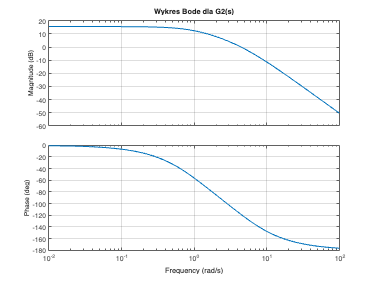

figure; 
bode(G2);
grid on;
title('Wykres Bode dla G2(s)');